This tutorial is based on content from the cbm manual, and the paper describing cbm.

Hiararchical parameter estimation is one approach used for characterising population parameters for a computational model. HPE uses an expectation-maximisation algorithm to 1. estimate individual parameters given the group-level distribution, and 2. update group parameters given current individual parameters. These two steps are completed on alternate iterations of the expectation-maximisation algorithm. HPE assumes that for a given model, all parameters are normally distributed.  HPE also assumes that a given model is responsible for generating data in all subjects because the model identity is included as a fixed effect. This means that during each participant has equal influence on group parameters, means and variances during parameter estimation, even if their data are better explained by alternative models. Furthermore, model comparison involves the evidence for each model across all subjects, which also treats a model as a fixed effect. Here, the authors extend the HPE approach by including an additional level to the hierarchy that specifies which model generated the data for each subject. model inference is then achieved through joint inferences over models and their parameters.

Mean-field variational Bayes is used for hierarchical bayesian inference as an extension of expectation-maximisation, because it is capable of handling multiple latent variables. There are four steps involved in each iteration of the hierarchical bayesian inference algorithm. 1. Calculate summary statistics, 2. update estimates of the posterior distribution for group parameters, 3. update esimates of the posterior for individual parameters, 4. update estimates of responsibility for each model in generating given data. 

First, we will prepare the behavioural data so that it is in a format that CBM likes. CBM likes data formatted as a cell array. Each cell within the array is a different participant. Within each participant structure there are three arrays. These arrays are called 'action', 'outcomes', and side. The action array contains the participant's choice for each trial. The 'outcomes' array includes the response to each choice. The 'side' array includes the key press for each choice. Please note, it is important to understand that trials where participants do not respond are removed at this stage, in line with current modelling approaches. Therefore, there may be differences in the size of action and outcome vectors between participants. The following code for data preparation is also available as a separate matlab script in this directory called 'prep_data.m'.

%reset the matlab environment before starting
clear 
clc
warning('off')
%initialise variable for output
data = {};
for id = ["00006","007",101,102,105,106,108,110,111,112,115,116,117,118,119,120,121,122,123,125,126,127,129,130,131,132,133,134,135]; %participants included in CBM analysis

    ppt = string(id);
    %load behavioural data
    %please ammend this path if you are not running this script on my machine
    file = 'C:\Users\Brendan\University of Reading\neuroade - Projects\project_SRfMRI\data\SRfMRI_' + ppt + '\SRfMRI_' + ppt + '.txt'; 
    df = readtable(file);
    %there is a quirk in the formatting of the text file that means the
    %following IDs need to be indexed differently. This does not impact the
    %output data
    if ppt ~= '007' && ppt ~= '103' && ppt ~= '110' && ppt ~= '112' && ppt ~= '117' && ppt ~= '118' && ppt ~= '119' && ppt ~= '123' && ppt ~= '127'
        %extract actions
        out.actions = table2array(df(:,7));
        %remove trials where no response was recorded
        out.actions(out.actions(:,1) ==0)=[];
        %extract outcomes
        out.outcome = table2array(df(:,15)) / 50;
        %remove trials where no response was recorded
        out.outcome(out.outcome(:,1) ==0)=[];
        %extract keypress
        out.side = string(table2array(df(:,14)));
        %remove trials where no response was recorded
        out.side(out.side(:,1) =='NaN')=[];
        %check if right key pressed
        out.right = out.side;
        out.right(out.right(:,1) == "r") = 1;
        out.right(out.right(:,1) == "b") = 0;
        out.right = str2double(out.right);
        %append data to cell array
        data{end+1} = out;
    else 
        out.actions = table2array(df(:,7));
        out.actions(out.actions(:,1) ==0)=[];
        out.outcome = table2array(df(:,16)) / 50;
        out.outcome(out.outcome(:,1) ==0)=[];
        out.side = string(table2array(df(:,15)));
        out.side(out.side(:,1) =='NaN')=[];
        out.right = out.side;
        out.right(out.right(:,1) == "r") = 1;
        out.right(out.right(:,1) == "b") = 0;
        out.right = str2double(out.right);
        data{end+1} = out;        
    end

end
%reshape cell array to a column vector
data = reshape(data, 29, 1);
%save output
save('all_data_mrs.mat', 'data')

In this task, participants completed a probabilistic reversal learning (PRL) task. In the PRL task participants were presented with two options, each was associated with a different probability of giving reward. One option resulted in reward 80% of the time, the other 20% of the time. Participants were tasked with maximising reward in the task. After demonstrating behaviourally that they understood which option was more rewarding, the reward probabilities of choices would change, such that the more rewarding option would become less rewarding (80% reward changes to 20%) and vice versa for the less rewarding option (20% reward changes to 80%). At this points, participants need to switch their preferential responding from one option to the other to continue maximising reward gain. 

First, we will load the behavioural data and check our models are compatiable with CBM. For the purpose of this tutorial we will use the following model files 'model_RL.m' and 'model_Kanen_4c.m' These models can be defined as:

[include model definition and formulae here]

clear 
%load the data
fdata = load("all_data_mrs.mat");
data = fdata.data;

%get data for one subject, create random parameters, and check the models
%run
subj1 = data{14};
parameters = randn(1,2)

parameters =    -0.3510    0.6232


loglik = model_RL(parameters, subj1)

loglik = -158.5789

parameters = randn(1,3)

parameters =     0.7990    0.9409   -0.9921


loglik = model_dualRL(parameters, subj1)

loglik = -195.9390

If we get log likelihood values returned for each of the models, then we know that our models are compatiable with CBM. These values should be real negative numbers. After checking the models run correctly, we can now use CBM to fit the models to our data. Firstly, the CBM function cbm_lap is used to fit a model to each participant separately. This model fit is non-hierarchical, and requires a normally distributed prior for each parameter; it uses Laplace approximation of the joint distribution of data and parameters to calculate maximum-a-posteriori estimates of parameters. A maximum-a-posteriori estimate is the mode of a posterior distribution; it is similar to the maximum likelihood esimation. Maximum likelihood esimation could be considered to be a case of maximum-a-posteriori esimation, with the prior being a uniform distribution. For the following section we will set the prior mean = 0 and variance = 6.25, in line with Daw et al (2019) [https://doi.org/10.1371/journal.pcbi.1007043](https://doi.org/10.1371/journal.pcbi.1007043).

%define the inputs needed for the function cbm_lap. These are:
% [CBM, SUCCESS] = cbm_lap(DATA, MODEL, PRIOR, FNAME, PCONFIG)
% DATA:  data (Nx1 cell) where N is number of samples
% MODEL: a function-handle to the model computing log-likelihood of DATA 
% given some paramete 
% PRIOR: a struct with two fields: mean and variance, as the gaussian prior
%   PRIOR.mu is a d-by-1 vector, where d is the number of parameters
%   (dimension)
%   PRIOR.variance is scaler or a vector or matrix indicating prior
%   variance. If it is scaler, prior variance is diagonal with 
%   PRIOR.variance as diagonal elements. If it is a vector, prior variance
%   is diag(PRIOR.variance).
% FNAME: filename for saving the output (leave it empty for not saving)
% PCONFIG: a struct for configuration (optional); see cbm_lap.m for more info
v = 6.25;
prior_RL = struct('mean',zeros(2,1),'variance',v);
prior_dualRL = struct('mean',zeros(3,1),'variance',v);
prior_Li_hybrid = struct('mean',zeros(3,1),'variance',v);
fname_RL = 'lap_RL_mrs.mat';
fname_dualRL = 'lap_dualRL_mrs.mat';

%now cbm_lap will be run for each of the models
cbm_lap(data, @model_RL, prior_RL, fname_RL);

cbm_lap                                           15-Jul-2021 08:25:59
Number of samples: 29
Number of parameters: 2

Number of initializations: 14
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
done :]


cbm_lap(data, @model_dualRL, prior_dualRL, fname_dualRL);

cbm_lap                                           15-Jul-2021 08:26:03
Number of samples: 29
Number of parameters: 3

Number of initializations: 21
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
Subject: 29
done :]


Now we can inspect the maximum-a-posteriori estimates from cbm_lap. These parameters are normally distributed, and their order is dependent on how the variables are coded in the model. The first column will be the first parameter and so on. Each row will represent the maximum-a-posterior estimate for each a given participant. 

fname = load('lap_RL_mrs.mat');
cbm = fname.cbm;
cbm.output.parameters

ans =     2.7807    0.4774
    3.3768    0.8852
    4.2681    0.8819
    1.9521    0.5320
    2.0636    0.5314
    3.2947    0.7979
    0.7053    0.1434
    1.7953    0.1336
    2.3531    0.2258
    2.9463    0.4119


fname = load('lap_dualRL_mrs.mat');
cbm = fname.cbm;
cbm.output.parameters

ans =     0.3209    3.3530    0.7174
    1.5026    3.4742    0.9552
   -0.2453    4.7268    1.4567
    0.0182    2.7421    0.8379
   -0.8420    3.9603    1.2921
    0.6445    3.4615    0.9803
   -0.8497    2.3005    0.5712
   -1.3518    3.5457    1.1006
    0.4658    3.3750    0.4004
    2.4859    2.7190    0.4241


Now  we can use the function cbm_hbi to do hierarchical bayesian inference. This function requires four inputs, these are:

cbm = cbm_hbi(data,models,fcbm_maps,fname,config,optimconfigs)

1st input: data for all subjects

2nd input: a cell input containing function handle to models

3rd input: another cell input containing file-address to files saved by cbm_lap

4th input: a file address for saving the output (optional)

5th input: is a struct, which configures hbi algorithm (optional); see cbm_hbi_config    

6th input: is another struct, which configures optimization algorithm (optional); see cbm_optim_config

%2nd input
models = {@model_RL, @model_dualRL};
%3rd input
fcbm_maps = {'lap_RL_mrs.mat','lap_dualRL_mrs.mat'};
fname = 'RL_mrs.mat';
cbm_hbi(data,models,fcbm_maps,fname);

cbm_hbi_hbi                                       15-Jul-2021 08:26:08
Running hierarchical bayesian inference (HBI)...

HBI has been initialized according to
	lap_RL_mrs.mat [for model 1]
	lap_dualRL_mrs.mat [for model 2]
 
Number of samples: 29
Number of models: 2
Iteration 01
Iteration 02
	model frequencies (percent)
	model 1: 38.8| model 2: 61.2| 
                                                           dL:    9.98
                                                           dm:   38.80
                                                           dx:    0.58
Iteration 03
	model frequencies (percent)
	model 1: 34.0| model 2: 66.0| 
                                                           dL:    2.38
                                                           dm:    4.84
                                                           dx:    0.23
Iteration 04
	model frequencies (percent)
	model 1: 32.7| model 2: 67.3| 
 

For each iteration of the model fitting cbm_hbi will report a percentage of the participants who are best explained by each of the models. It will also report the change in log-likelihood of all data from the previous iteration, given the model space (dL); the percentage change in model frequencies from the previous iteration (dm); and the changes in parameters from the previous iteration (dx). By default, cbm_hbi stops when dx <0.01.

Now we will inspect the output from cbm_hbi

fname_hbi = load('RL_mrs.mat');
cbm = fname_hbi.cbm;
cbm.output

ans = struct with fields:
                     parameters: {2×1 cell}
                 responsibility: [29×2 double]
                     group_mean: {[2.6608 0.2497]  [-0.1582 3.8207 0.6169]}
    group_hierarchical_errorbar: {[0.4300 0.0918]  [0.2791 0.3874 0.0742]}
                model_frequency: [0.3199 0.6801]
                exceedance_prob: [0.0273 0.9727]
      protected_exceedance_prob: [NaN NaN]


cbm.output.parameters will give you the parameters for each subject for each model

cbm.output.responsibility will describe the estimated responsibility that each model generated each individual's data. These sum to 1 for each subject. 

cbm.output.group_mean will give you the group mean for each parameter. These parameters are normally distributed because hierarchical bayesian inference assumes that parameters are normally distributed.

cbm.output.group_hierarchical_errorbar will give you the error for each group level parameter (standard mean error)

cbm.output.model_frequency will give you an estimate of how much each model is expressed across the group. This is useful for model comparison.

cbm.output.exceedance_prob will give you the probability that each model is the most likely model across the group

cbm.output.protected_exceedance_prob will give you the probability that each model is the most likely model across the group while accounting for the null hypothesis that no model is most likely.

Now we will plot the group parameters for the models.

plotting the group parameters of the most frequenct modelThere is no protected exceedance probability as cbm_hbi_null has not been executed
Plotting exceedance probability instead...


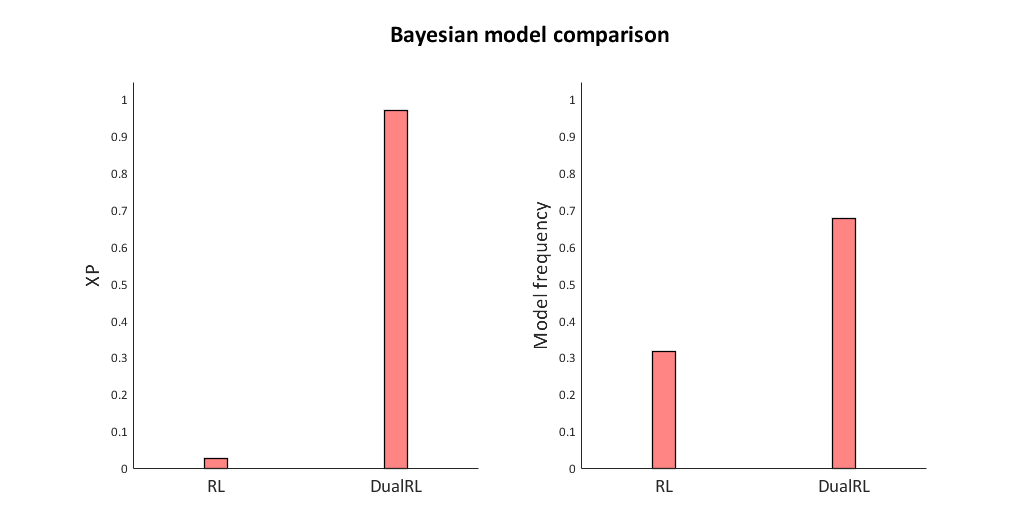

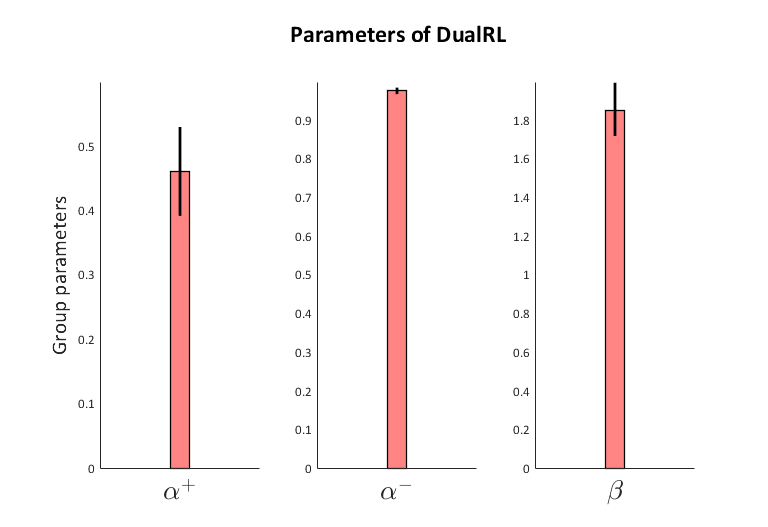

model_names = {'RL','DualRL'};
param_names = {'\alpha^+','\alpha^-','\beta'};
transform = {'sigmoid','sigmoid','exp'};
cbm_hbi_plot('RL_mrs.mat', model_names, param_names, transform);

Now we will re-run HBI under the null hypothesis that no model is most likely across the population

cbm_hbi_null(data,'RL_mrs.mat')

cbm_hbi_hbi                                       15-Jul-2021 08:26:14
Running hierarchical bayesian inference (HBI)- null mode...

HBI has been initialized according to
	lap_RL_mrs.mat [for model 1]
	lap_dualRL_mrs.mat [for model 2]
 
Number of samples: 29
Number of models: 2
Iteration 01
Iteration 02
                                                           dL:    3.64
                                                           dx:    0.39
Iteration 03
                                                           dL:    0.39
                                                           dx:    0.09
Iteration 04
                                                           dL:    0.13
                                                           dx:    0.02
Iteration 05
                                                           dL:    0.09
                                                           dx:    0.01
Iteration 06
     

ans = struct with fields:
        method: 'hbi'
         input: [1×1 struct]
       profile: [1×1 struct]
          math: [1×1 struct]
        output: [1×1 struct]
    exceedance: [1×1 struct]


fname_hbi = load('RL_mrs.mat');
cbm = fname_hbi.cbm;
xp = cbm.output.exceedance_prob

xp =     0.0273    0.9727


pxp = cbm.output.protected_exceedance_prob

pxp =     0.0273    0.9727


For each iteration cbm will report the change in log-likelihood of all data from the previous iteration, given the model space (dL); and the changes in parameters from the previous iteration (dx). You will also be able to seed the exceedance probability (xp) and the protected exceedance probability (pxp). We can now re-plot the model comparison parameters as we have pxp values.

plotting the group parameters of the most frequenct model

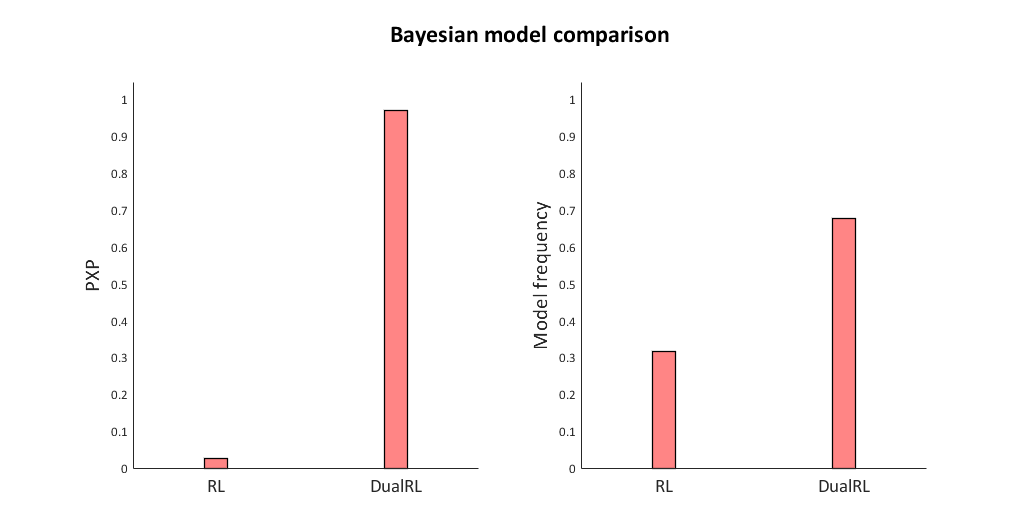

model_names = {'RL','DualRL'};
%param_names = {'\alpha^0','\eta','\kappa'};
param_names = {'\alpha^+','\alpha^-','\beta'};
transform = {'sigmoid','sigmoid','exp'};
%transform = {'exp','sigmoid','sigmoid'};
cbm_hbi_plot('RL_mrs.mat', model_names, param_names, transform);